clear all, close all;
addpath('..\');

setenv('PATH', [getenv('PATH') ';C:\tools\Xilinx\Vivado\2024.1\bin']);


%SAMPLING_FREQ = (50*16*16);
SAMPLING_FREQ = 10^8;
BUFFER_LEN = 2048;
SIM_TIME = 12*BUFFER_LEN/SAMPLING_FREQ

SIM_TIME = 2.4576e-04

FREQ = SAMPLING_FREQ*(0 : BUFFER_LEN-1)/BUFFER_LEN;
MAIN_FREQ_INDEX = 9;
csv_read;

out = sim("hdl_model_fixed.slx")

out =   Simulink.SimulationOutput:

                   tout: [44801x1 double] 
                   yout: [1x1 Simulink.SimulationData.Dataset] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


sim_FFT_Re= out.yout{1}.Values;
sim_FFT_Im= out.yout{2}.Values;
sim_MAX = out.yout{3}.Values;
sim_MIN = out.yout{4}.Values;
sim_THD = out.yout{5}.Values;
sim_BUF = out.yout{6}.Values;
sim_RMS = out.yout{7}.Values;
sim_VAL = out.yout{8}.Values;

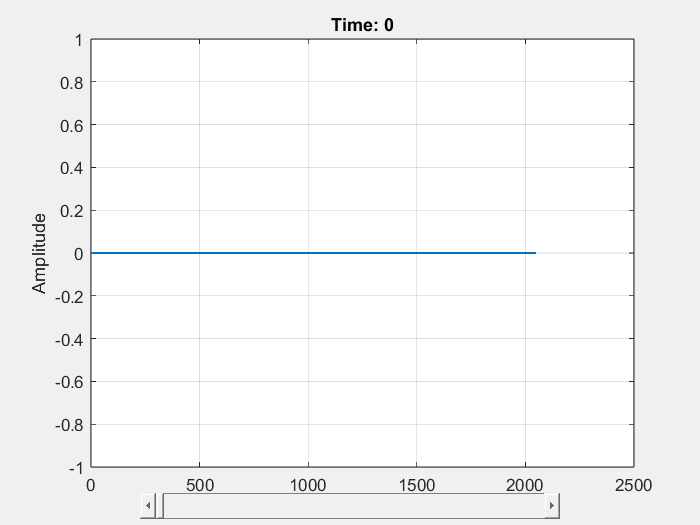

FFT_abs = timeseries(abs(sim_FFT_Re.Data + sim_FFT_Im.Data*1i), sim_FFT_Re.Time);

slidePlotTimeSeries(FFT_abs);

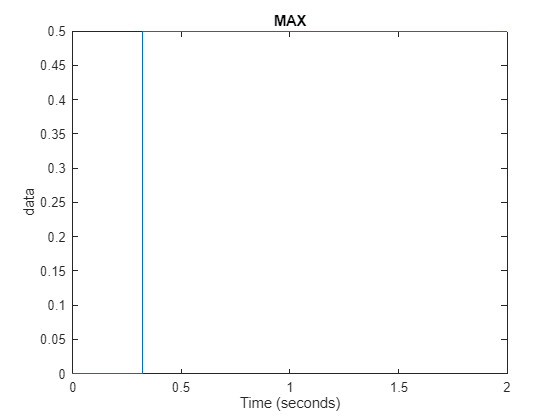


figure;
plot(sim_MAX);
title("MAX")

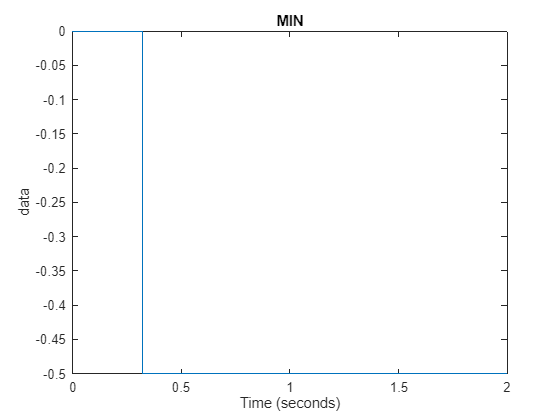


figure;
plot(sim_MIN);
title("MIN")

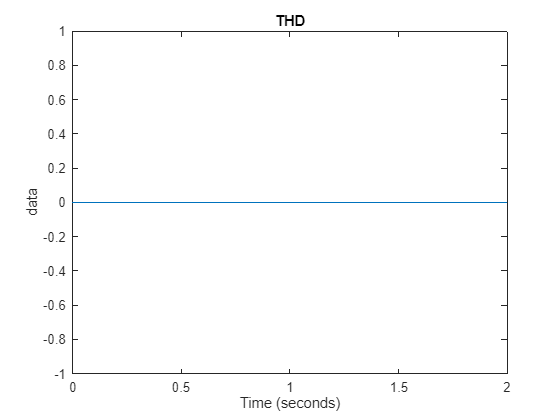


figure;
plot(sim_THD);
title("THD")

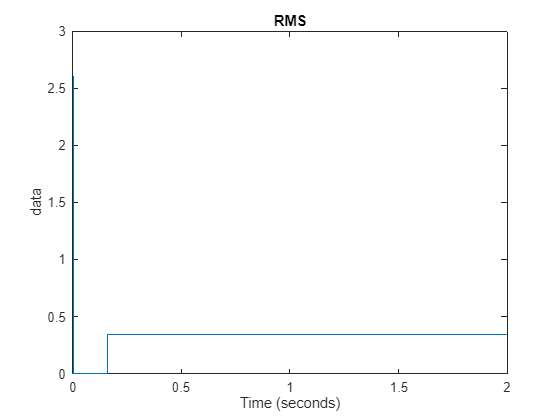


figure;
plot(sim_RMS);
title("RMS")

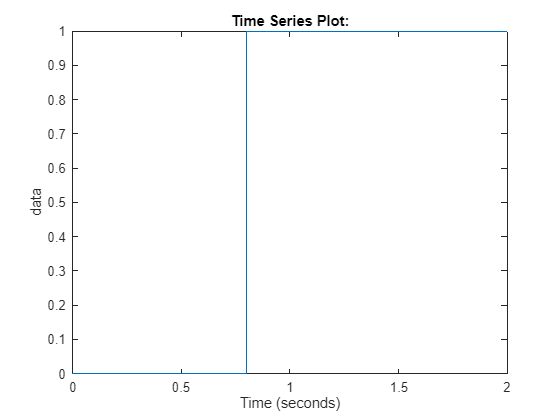



%slidePlotTimeSeries(sim_BUF);

figure;
plot(sim_VAL);